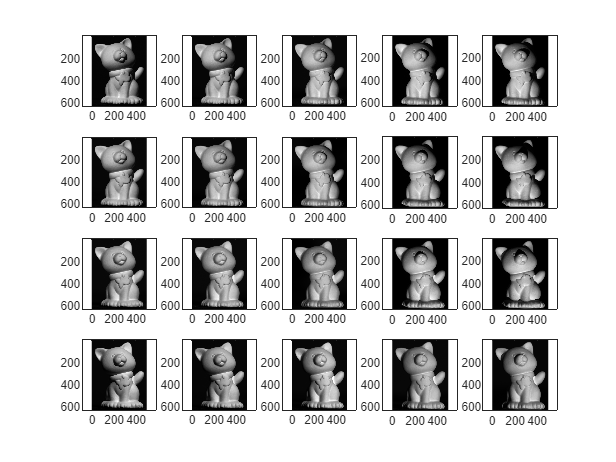

num_images = 20;
images = cell(num_images, 1);
for i = 1:num_images
    s = int2str(i);
    if i < 10
        s = "0" + s;
    end
    images{i} = imread("PSData/cat/Objects/Image_" + s + ".png");

    subplot(4, 5, i);
    imagesc(images{i});
    colormap gray;
    axis equal;
end

sz = size(images{1});

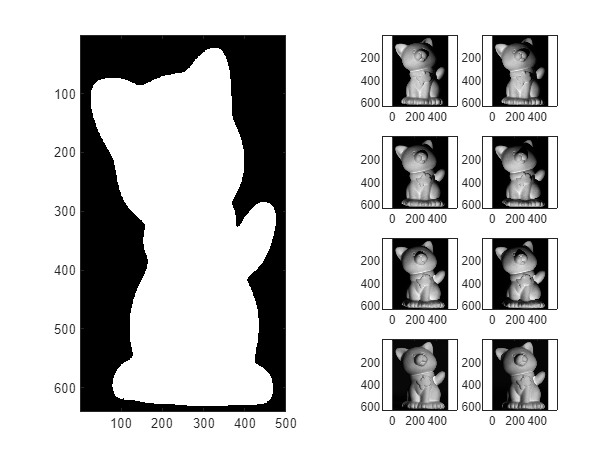

mask = zeros(sz);
threshold = 30;
for i = 1:num_images
    mask = mask | images{i} > threshold;
end
subplot(1, 2, 1);
imagesc(mask);
colormap gray;

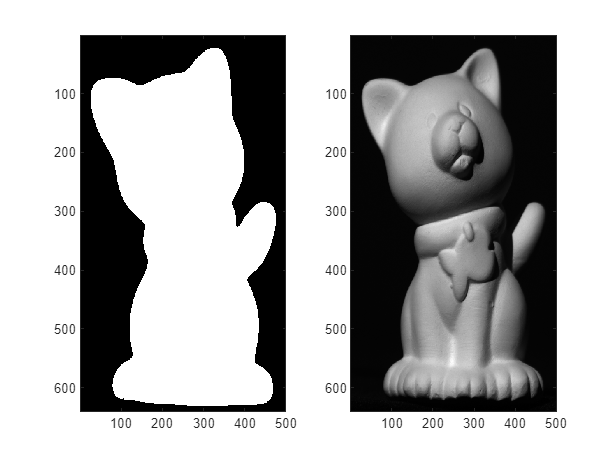

subplot(1, 2, 2);
imagesc(images{1});
colormap gray;

p = nnz(mask);
I = zeros(p, num_images);
for i = 1:num_images
    I(:,i) = images{i}(mask);
end

[U, Sigma, V] = svd(I, 'econ');
V = V';
U_prime = U(:, 1:3);
Sigma_prime = Sigma(1:3, 1:3);
V_prime = V(1:3, :);

Sigma_root = Sigma_prime .^ 0.5;
S_hat = U_prime * Sigma_root;
L_hat = Sigma_root * V_prime;
norm(S_hat * L_hat - I, 'fro') / norm(I, "fro")

ans = 0.0537